clear
addpath("frffit"); addpath('Assignment 2')


a) transfer function

m = 1; %[kg]
wc = 10*2*pi %[Hz} crossover frequency hertz

wc = 62.8319


H = tf(1,[m 0 0])

H =
 
   1
  ---
  s^2
 
Continuous-time transfer function.
Model Properties




P = abs(m*wc^2/(1 + i))

P = 2.7915e+03

D = P/(wc)

D = 44.4288

C = tf([D P],1)

C =
 
  44.43 s + 2792
 
Continuous-time transfer function.
Model Properties


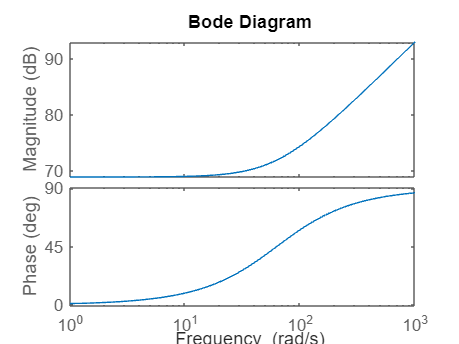

bode(C)

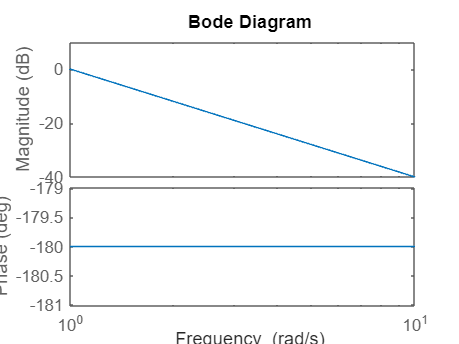

bode(H)

H*C

ans =
 
  44.43 s + 2792
  --------------
       s^2
 
Continuous-time transfer function.
Model Properties


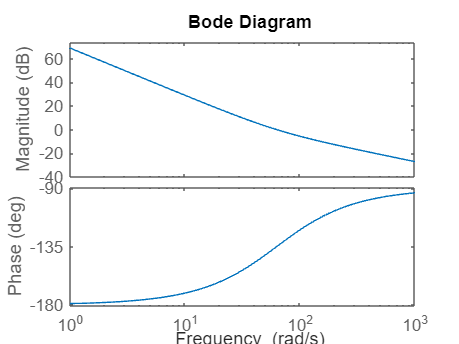

bode(H*C)

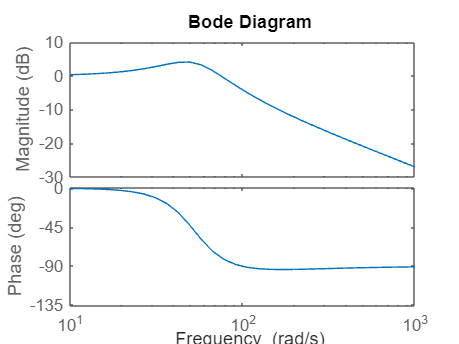


bode(H*C/(1+H*C))

c) running simulation

fs = 1000 %[Hz]

fs = 1000

stepsize = 1/fs %[s]

stepsize = 1.0000e-03

max_freq = log10(fs/2) 

max_freq = 2.6990

t_end = 120; %[s]

out = sim("two");
u = out.u;
d = out.d;

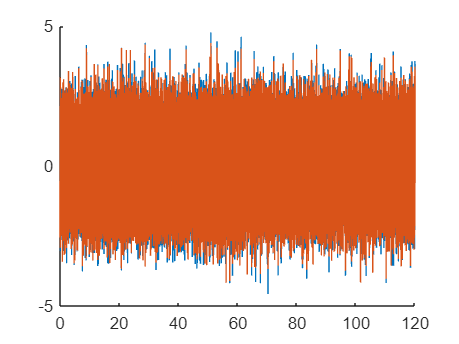

min_freq = 0.25*2*pi; %[rad/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds

nfft = round(windowsize/stepsize); %window size in data points
%nfft = 1/min_freq*window; 
n_overlap = nfft/2;

figure()
hold on     
plot(u.Time,u.Data)
plot(d.Time,d.Data)
hold off

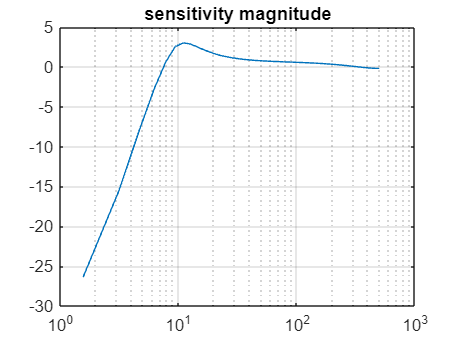



%Tf estimate
[Sud, F] = tfestimate(d.Data,u.Data,hann(nfft),[],nfft,fs); %cross spectral power density
Sdd = pwelch(d.Data,hann(nfft)); %spectral power disturbance
Suu = pwelch(u.Data,hann(nfft)); %spectral power input
%S =  Sud./Sdd; %sensitivity function
S = Sud;
semilogx(F,mag2db(abs(S)))
title("sensitivity magnitude")
grid on

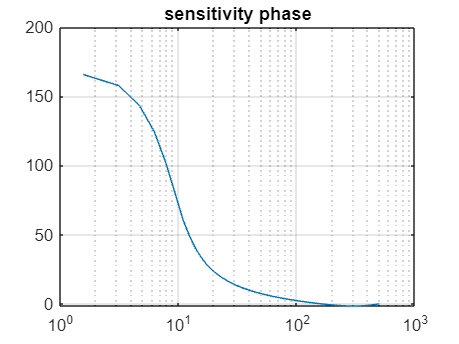


semilogx(F,angle(S)/pi*180)
title('sensitivity phase')
grid on

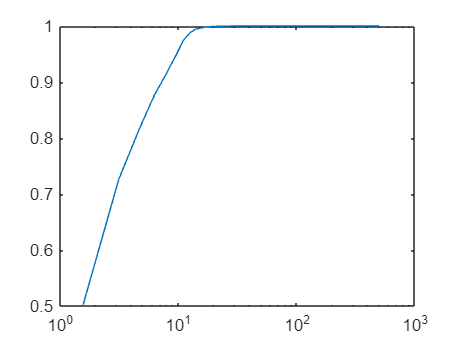


%plotting coherence 
[coherence_ry, f] = mscohere(d.Data,u.Data,hann(nfft),[],nfft,fs);
semilogx(f,coherence_ry)

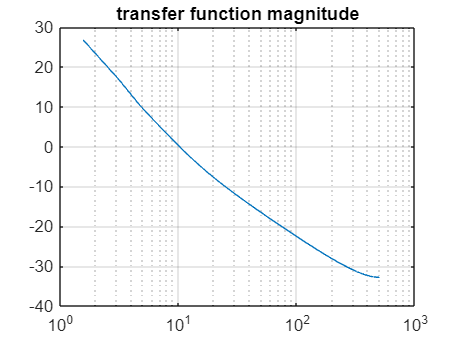

    
%plotting transfer function
L = 1./S - 1;
semilogx(F,mag2db(abs(L)))
title('transfer function magnitude')
grid on

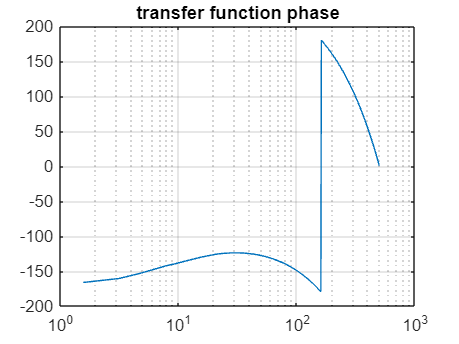


semilogx(F,angle(L)/pi*180)
title('transfer function phase')
grid on